## Problem 1

%In a lowpass filter you want no gain on low frequencies and high
%attenuation on high frequencies.
z = tf('z',-1)

z =
 
  z
 
Sample time: unspecified
Discrete-time transfer function.



H = (z+1)^2/((z-0.5)*(z-0.9))

H =
 
    z^2 + 2 z + 1
  ------------------
  z^2 - 1.4 z + 0.45
 
Sample time: unspecified
Discrete-time transfer function.



num1 = [1,2,1]

num1 =      1     2     1


den1 = [1,-1.4,0.45]

den1 =     1.0000   -1.4000    0.4500


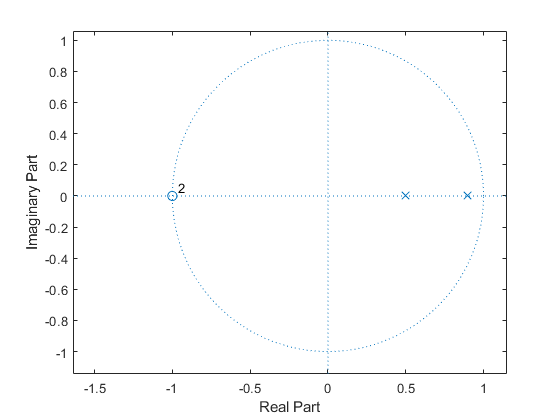

zplane(num1,den1)

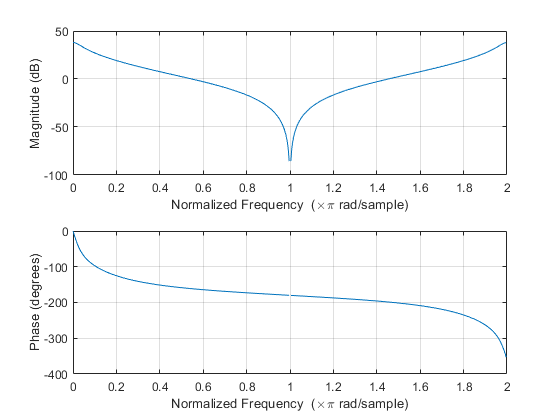

freqz(num1,den1,'whole')


%In a highpass filter attenuation on low frequencies and gain on high
%frequencies
H2 =(z-1)^2/((z+0.5)*(z+0.9))

H2 =
 
    z^2 - 2 z + 1
  ------------------
  z^2 + 1.4 z + 0.45
 
Sample time: unspecified
Discrete-time transfer function.



num2 = [1,-2,1]

num2 =      1    -2     1


den2 = [1,1.4,0.45]

den2 =     1.0000    1.4000    0.4500


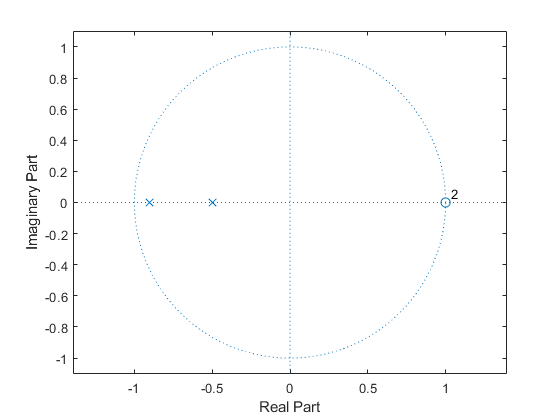

zplane(num2,den2)

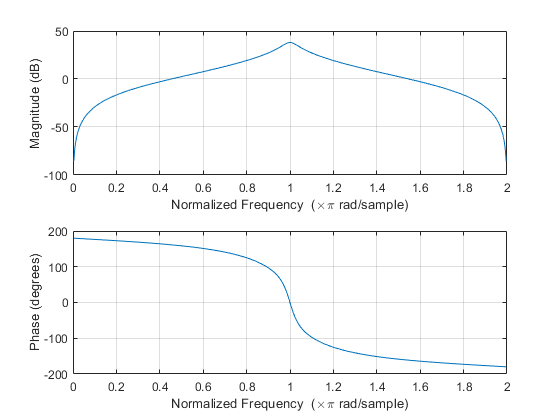

freqz(num2,den2,'whole')

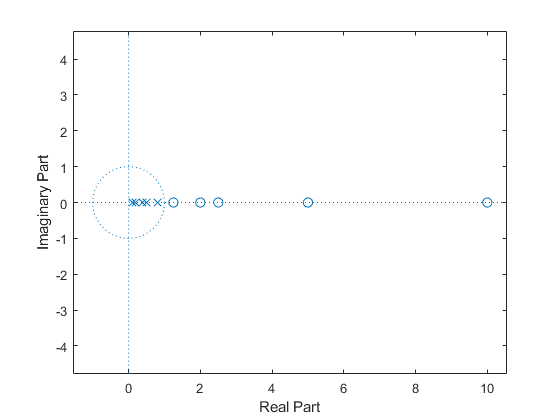


%For an all pass filter, the pole placement have to be the reciprocal of
%the zero placement.
a1 = 0.1;
a2 = 0.2;
a3 = 0.4;
a4 = 0.5;
a5 = 0.8;
H3 = (z-1/a1)*(z-1/a2)*(z-1/a3)*(z-1/a4)*(z-1/a5)/((z-a1)*(z-a2)*(z-a3)*(z-a4)*(z-a5));
num3 = [1,-20.75, 146.875,-453.125,625,-312.5];
den3 = [1,-2,1.45,-0.47,0.0664,-0.0032];
zplane(num3,den3)

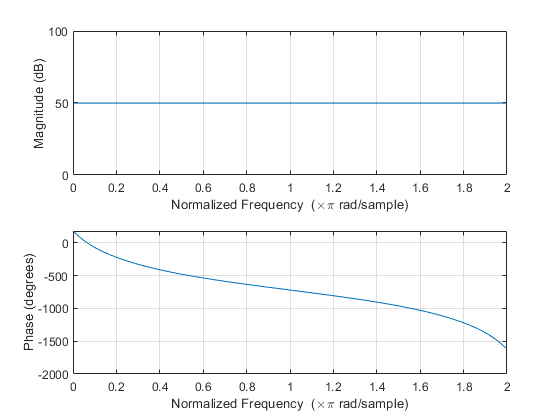

freqz(num3,den3,'whole')
ylim([0 100])

%As can be seen from the frequency response, the filter has the constant
%magnitude response for all frequencies.

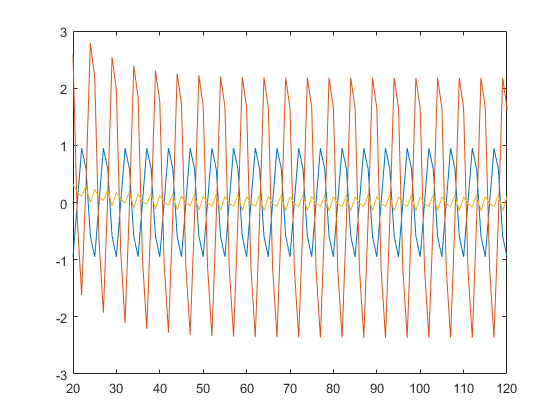

[time,f] = generate_sinusoid(1,100,0,500,1);
[time,f2] = generate_sinusoid(1,200,0,500,1);
[h,t] = impz(num1,den1);
y1 = conv(f,h);
y2 = conv(f2,h);
plot(f)
hold on
plot(y1)
plot(y2)
hold off
xlim([20 120])

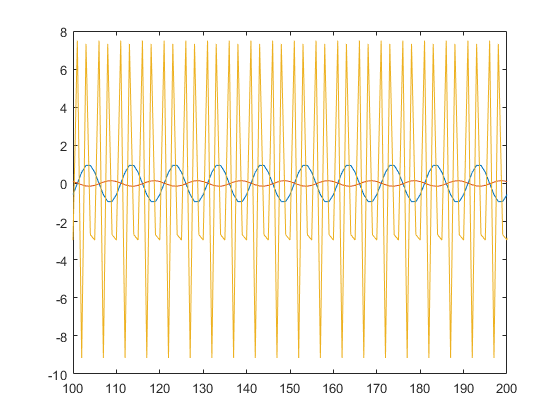

[time1 a] = generate_sinusoid(1,50,0,500,1);
[time1 a2] = generate_sinusoid(1,200,0,500,1);
[h2,t2] = impz(num2,den2);
y21 = conv(a,h2);
y22 = conv(a2,h2);
plot(a)
hold on
plot(y21)
plot(y22)
hold off
xlim([100 200])

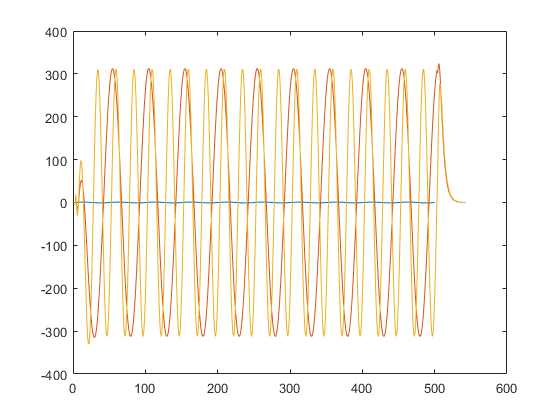

[time1 b] = generate_sinusoid(1,10,0,500,1);
[time1 b2] = generate_sinusoid(1,20,0,500,1);
[h3,t3] = impz(num3,den3);
y31 = conv(b,h3);
y32 = conv(b2,h3);
plot(b)
hold on
plot(y31)
plot(y32)
hold off

%We observe what we predicted. Signals with specific frequencies are either
%attenuated or amplified. Furthermore, they are also phase shifted.

%The suppressed frequencies depend on the sampling frequency, because in
%the frequency response the frequency axis is normalized with fs/2. So if
%you set fs = 50, then a signal with f = 20Hz will have a relatively very
%high frequency, despite it being an absolute rather slow frequency.

%The addition for poles and zeroes causes the magnitude response to
%increase or decrease at certain frequencies. If you place many poles you
%will amplify the signal a lot at certain frequencies and the opposite
%happens with zeroes.

%With the zero/pole plot you can find the transfer function. And with that,
%you can find the frequency response and find the magnitude and phase shift
%for the signals.

## Problem 2

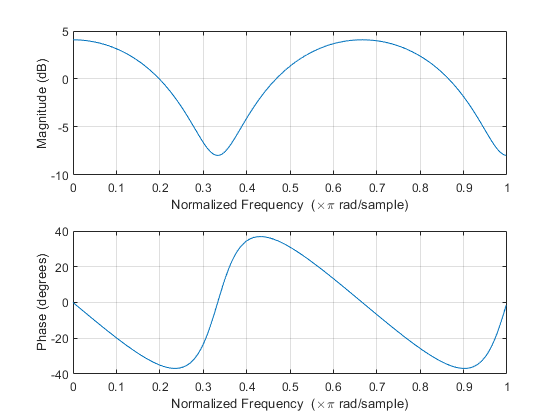

% y(n) = x(n) + a*x(n-delay)
%The FIR filter
alpha = 0.6;
num4 = [1,0,0,alpha];
den4 = [1,0,0,0];
freqz(num4,den4)

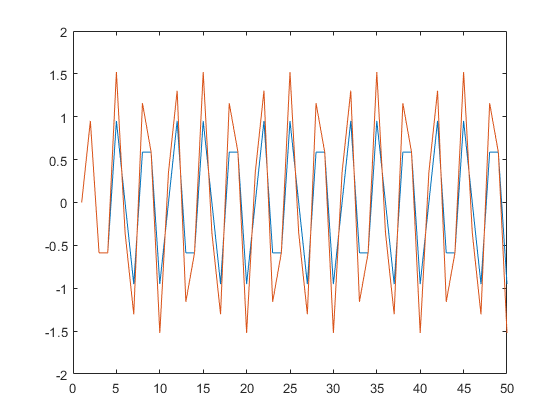

[h4,t4] = impz(num4,den4);
[time20 c] = generate_sinusoid(1,30,0,100,1);
y200 = filter(num4,den4,c);
plot(c)
hold on
plot(y200)
hold off
xlim([0 50])

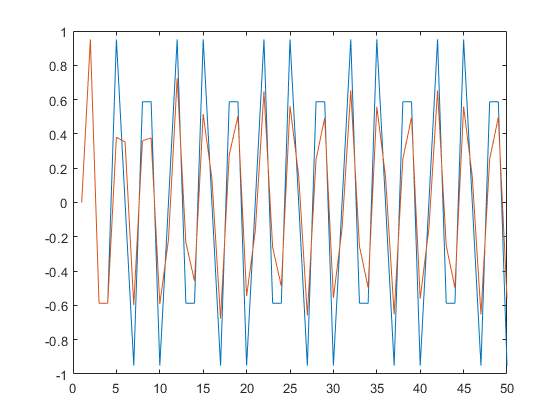


%y(n) = x(n) - a*y(n-delay)
%The IIR filter
num5 = [1,0,0,0];
den5 = [1,0,0,alpha];
[h5,t5] = impz(num5,den5);
y201 = conv(c,h5);
plot(c)
hold on
plot(y201)
hold off
xlim([0 50])

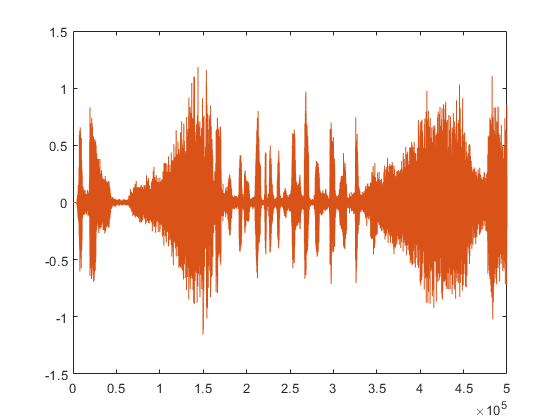

[y,fs] = audioread("mini-me_short.wav");
y202 = filter(num4,den4,y);
plot(y)
hold on
plot(y202)
hold off

## Problem 1.2.2

%Check the hands_on file from week one to find the solution

## Problem 3.1.3

%Plotting signal
[y,fs] = audioread('piano.wav');
t = 0:1/fs:9.277;
audioinfo("piano.wav")

ans = struct with fields:
             Filename: 'C:\Users\Frederik\Desktop\22051\piano.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 409116
             Duration: 9.2770
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


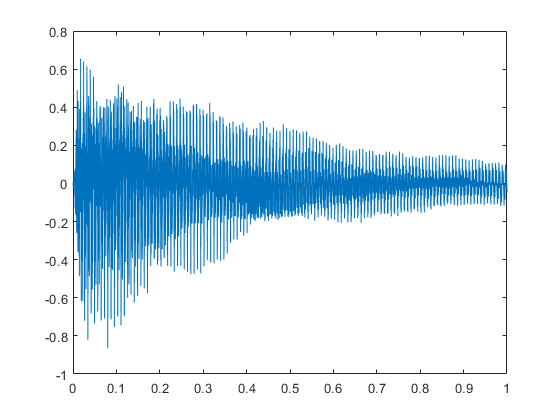

plot(t,y)
xlim([0 1])

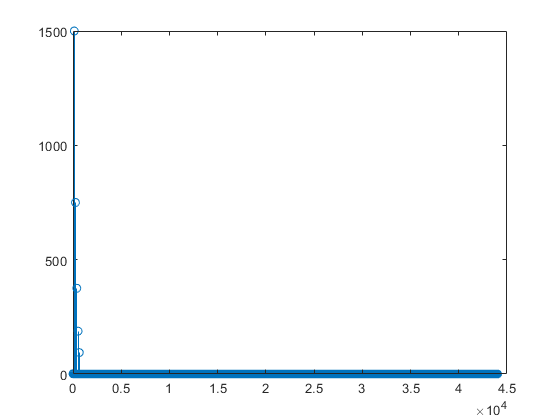


%Plotting spectrum
%Use signal analyzer

%Finding the fundamental frequency is done with MATLABs signal analyzer
%We look at the first peak, and find that f0 = 130.5Hz
f0 = 130.5;

%We synthesize a signal with all component having same phase
N = 10;
T = 2;
ak = 1500;
delta_f = 1/T;
t2 = 0:delta_f:fs;
n = 1;
n2 = length(t2);
u = zeros(n2,1);
u(1) = 1;
for c=1:5
    u(2*n*f0+1) = ak;
    ak = ak*0.5;
    n = n+1;
end
stem(t2,u)

x = ifft(u,'symmetric')

x =     0.0659
    0.0659
    0.0657
    0.0654
    0.0651
    0.0646
    0.0641
    0.0634
    0.0627
    0.0618


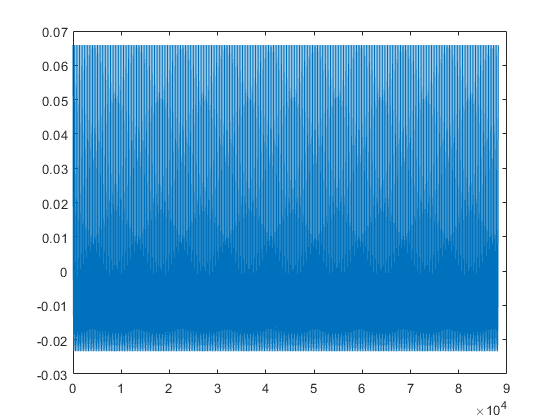

plot(x)

%If we use the sound command, we hear that they both sound pretty
%identical, at least when the piano tone is deacying.


%Now we synthesize a signal with all components having arbitrary phase
N = 10;
T = 2;
ak = 1200;
bk = 1200;
delta_f = 1/T;
t2 = 0:delta_f:fs;
n = 1;
n2 = length(t2);
u = zeros(n2,1);
u(1) = 1;
for c=1:5
    u(2*n*f0+1) = ak+i*bk;
    ak = ak*0.5;
    bk = bk*0.3;
    n = n+1;
end
x = ifft(u,'symmetric')

x =     0.0527
    0.0517
    0.0505
    0.0493
    0.0480
    0.0466
    0.0452
    0.0437
    0.0421
    0.0405


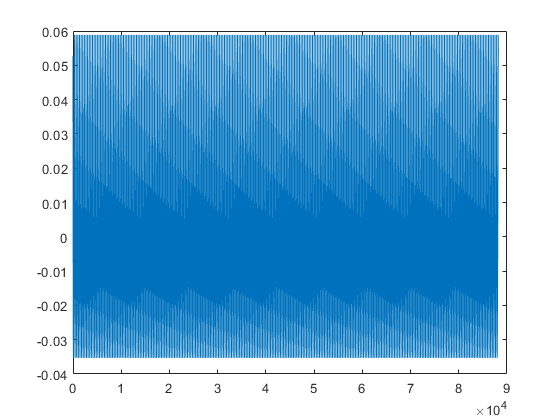

plot(x)

%The phase doesn't seem to have the biggest impact on the synthesized
%signal.